Choose the data set and make sure the name corresponds


dataSet = "SqueezeNet";
logits = squeezenet_logits(1:1000,:);

dataSet = "AlexNet";
logits = alex_logits(1:1000,:);

dataSet = "GoogleNet-places";
logits = googP_logits(1:1000,:);



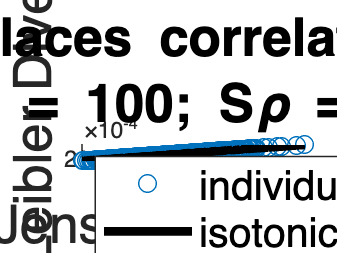

introduce_functions;
temperature = 100;

%create a vector with first element 1 and the others zero
Y_logit = zeros(1,size(logits,2));
Y_logit(1) = 1;

smData = soft_max(logits,temperature);
smYData = soft_max(Y_logit,temperature);

dists1 = KLD(smYData,smData);
dists2 = JSD(smYData,smData);


chart_title1 = strcat(dataSet," correlation: KLD/JSD");
chart_title2 = strcat("t = ",num2str(temperature));
chart_title = [chart_title1,chart_title2];

shepard_spear(dists1,dists2,chart_title,"Jensen-Shannon","Kullback-Leibler Divergence");